% Open file to be transmitted and create bytestream

fid = fopen('vsmall.txt');
x=fread(fid,'*char');
byteArr = dec2bin(x,8);
byteArrTransposed=transpose(byteArr);
binaryStream=byteArrTransposed(:)-'0';
numRSPackets=ceil(length(byteArr)/223);
data=zeros(223*8*numRSPackets,1);
data(1:length(binaryStream))=binaryStream;
%data=zeros(223*8,1)
%data(1:223*8)=binaryStream(1:223*8)

%create encoder
n=255;
k=223;
rsencoder = comm.RSEncoder(n,k,'BitInput',true);
rsdecoder = comm.RSDecoder(n,k,'ErasuresInputPort',true,'NumCorrectedErrorsOutputPort',true,'BitInput',true);

%encode data and generate images
encData=rsencoder(data);

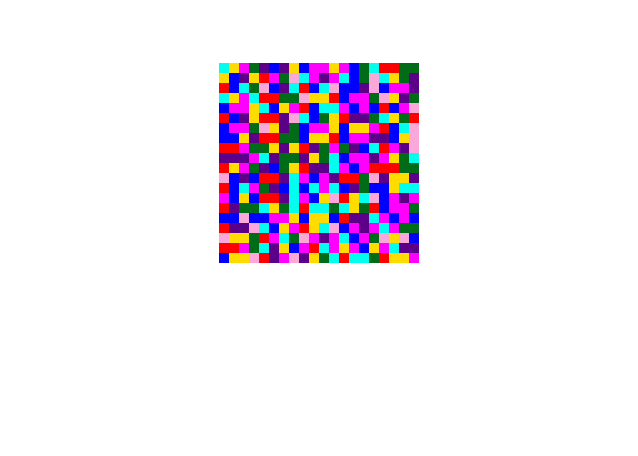

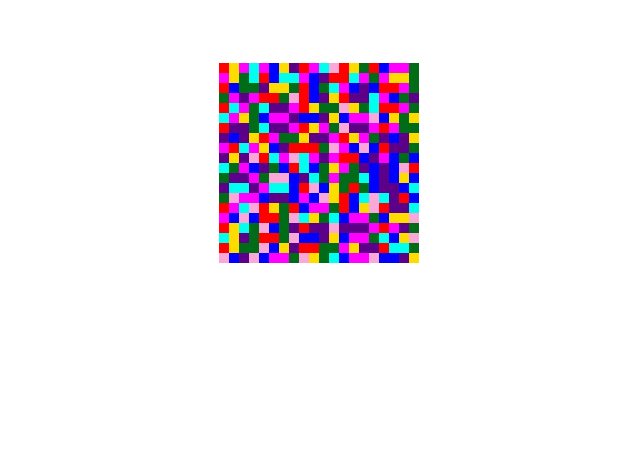

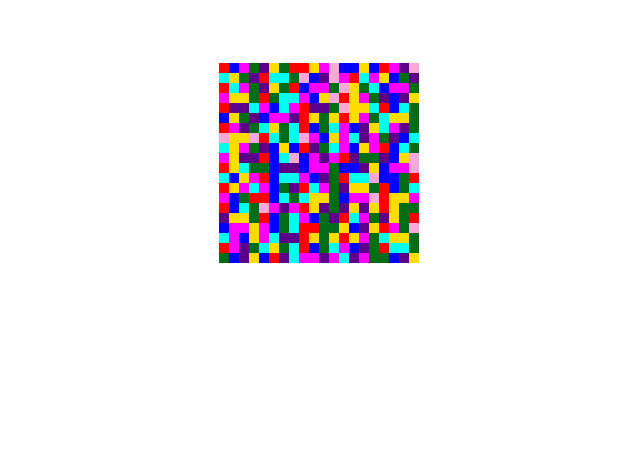

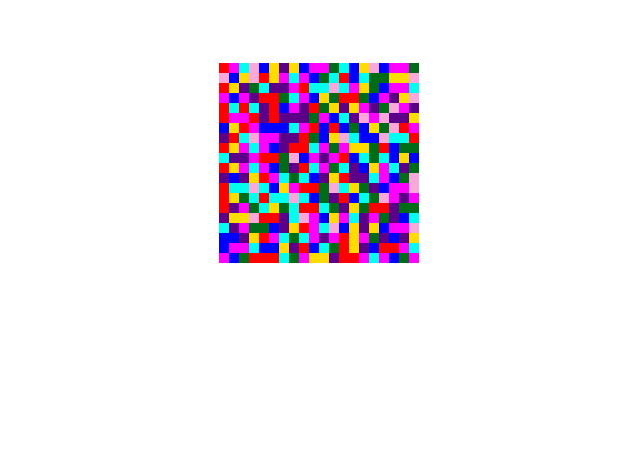

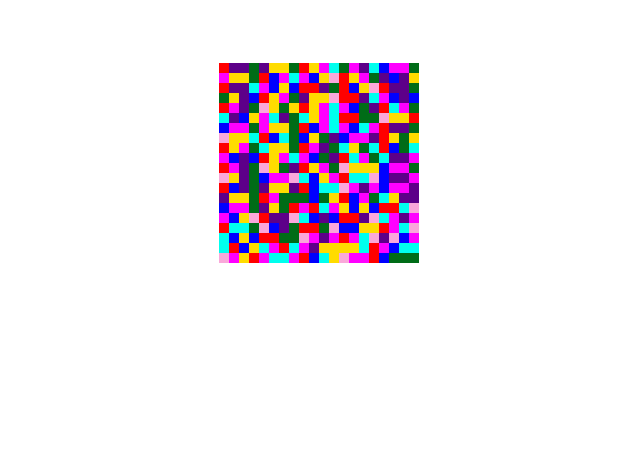

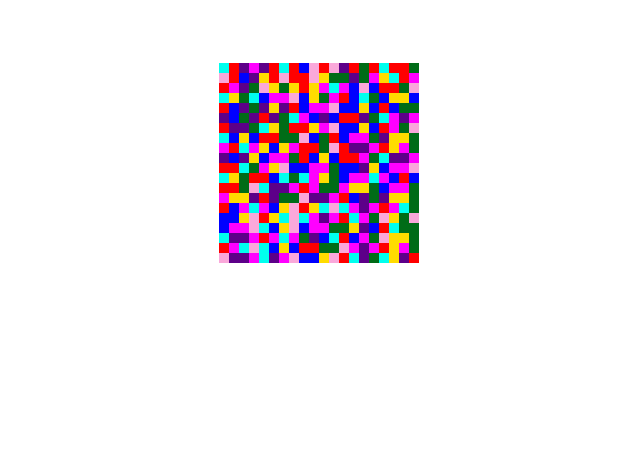

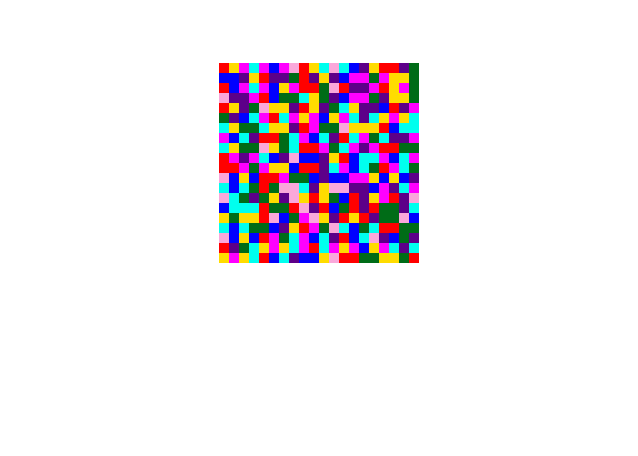

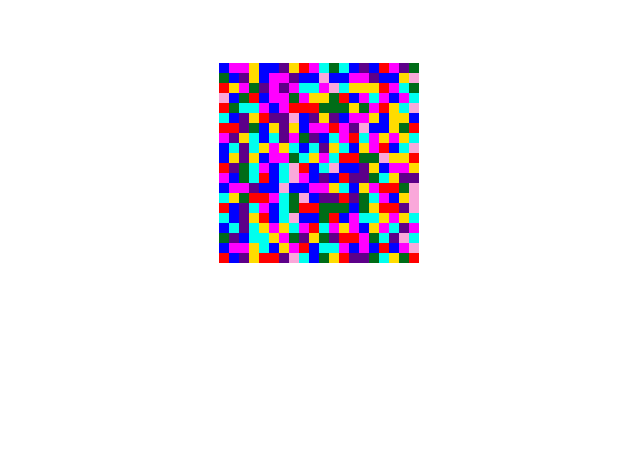

[image,byteStream]=generateImages(encData,20,10);

generateVideo(image);

cd 'C:\Program Files (x86)\VideoLAN\VLC'
!vlc  "C:\Users\eitan\OneDrive\Documents\Fourth Year Files\Research project 2\AILensCleaner\Modulation\myVideo.avi" --fullscreen --no-loop


%decoder code. will remove later
erasuresvector=zeros(1785,1)
[binaryStream,errs] = rsdecoder(encData,erasuresvector)
binaryStream=binaryStream';
for i=1:223
    binaryReceived=string(binaryStream((i-1)*8+1:(i)*8));
    binaryReceived=strjoin(binaryReceived);
    textReceived = char(bin2dec(binaryReceived))
end

filename='received2.txt';
fid = fopen(filename,'w');
fprintf(fid,'%s',textReceived);
fclose(fid);


function y=generateVideo(image)
    numImages=size(image);
    numImages=numImages(4);
    images=cell(numImages,1);
    for i=1:numImages
        images{i}=image(:,:,:,i);
    end
    
     writerObj = VideoWriter('myVideo.avi');
     writerObj.FrameRate = 1;
     writerObj.Quality=100;
     % set the seconds per image
     framerate = 3;
     % open the video writer
     open(writerObj);
     % write the frames to the video
     for u=1:length(images)
         % convert the image to a frame
         frame = im2frame(images{u});
         if u==length(images)
             framerate=framerate+1;
         end
         for v=1:framerate
             
             
             writeVideo(writerObj, frame);
         end
     end
     % close the writer object
     close(writerObj);
end

function [image,byteStream] =generateImages(bitstream,size,pixelsize) % generates images from bitstream
byteStream="";
symbolsPerFrame=size*size;
numFrames=length(bitstream)/(3*symbolsPerFrame);

if (mod(numFrames,1)~=0)%need to generate padding
    numcompleteframes=floor(numFrames);
    numAdditionalSymbols=3*((size*size)-(length(bitstream)/3-symbolsPerFrame*numcompleteframes));
    bitstream(end:end+numAdditionalSymbols)=0;
    numcompleteframes=numcompleteframes+1;
end

image=zeros(pixelsize*size,pixelsize*size,3,numcompleteframes); %initialize
for j=1:numcompleteframes
    for i=(j-1)*size*size+1:(j)*size*size

        row = floor((i-1)/size)+1;
        col=(i)-(row-1)*size;
        row=mod(row,size);
        if (row==0)
            row=size;
        end

        symbol = num2str(bitstream(3*(i-1)+1:3*(i))');
        
        switch symbol
            case('0  0  0')
                imageTemp(((row-1)*pixelsize+1):((row-1)*pixelsize+pixelsize),((col-1)*pixelsize+1):((col-1)*pixelsize+pixelsize),1)=255/255;
                imageTemp(((row-1)*pixelsize+1):((row-1)*pixelsize+pixelsize),((col-1)*pixelsize+1):((col-1)*pixelsize+pixelsize),2)=0;
                imageTemp(((row-1)*pixelsize+1):((row-1)*pixelsize+pixelsize),((col-1)*pixelsize+1):((col-1)*pixelsize+pixelsize),3)=255/255;
                byteStream=byteStream+"0";
            case('0  0  1')
                imageTemp(((row-1)*pixelsize+1):((row-1)*pixelsize+pixelsize),((col-1)*pixelsize+1):((col-1)*pixelsize+pixelsize),1)=0;
                imageTemp(((row-1)*pixelsize+1):((row-1)*pixelsize+pixelsize),((col-1)*pixelsize+1):((col-1)*pixelsize+pixelsize),2)=0;
                imageTemp(((row-1)*pixelsize+1):((row-1)*pixelsize+pixelsize),((col-1)*pixelsize+1):((col-1)*pixelsize+pixelsize),3)=255/255;
                byteStream=byteStream+"1";
            case('0  1  0')
                imageTemp(((row-1)*pixelsize+1):((row-1)*pixelsize+pixelsize),((col-1)*pixelsize+1):((col-1)*pixelsize+pixelsize),1)=0;
                imageTemp(((row-1)*pixelsize+1):((row-1)*pixelsize+pixelsize),((col-1)*pixelsize+1):((col-1)*pixelsize+pixelsize),2)=255/255;
                imageTemp(((row-1)*pixelsize+1):((row-1)*pixelsize+pixelsize),((col-1)*pixelsize+1):((col-1)*pixelsize+pixelsize),3)=238/255;
                byteStream=byteStream+"2";
            case('0  1  1')
                imageTemp(((row-1)*pixelsize+1):((row-1)*pixelsize+pixelsize),((col-1)*pixelsize+1):((col-1)*pixelsize+pixelsize),1)=255;
                imageTemp(((row-1)*pixelsize+1):((row-1)*pixelsize+pixelsize),((col-1)*pixelsize+1):((col-1)*pixelsize+pixelsize),2)=0;
                imageTemp(((row-1)*pixelsize+1):((row-1)*pixelsize+pixelsize),((col-1)*pixelsize+1):((col-1)*pixelsize+pixelsize),3)=0;
                byteStream=byteStream+"3";
            case('1  0  0')
                imageTemp(((row-1)*pixelsize+1):((row-1)*pixelsize+pixelsize),((col-1)*pixelsize+1):((col-1)*pixelsize+pixelsize),1)=93/255;
                imageTemp(((row-1)*pixelsize+1):((row-1)*pixelsize+pixelsize),((col-1)*pixelsize+1):((col-1)*pixelsize+pixelsize),2)=0;
                imageTemp(((row-1)*pixelsize+1):((row-1)*pixelsize+pixelsize),((col-1)*pixelsize+1):((col-1)*pixelsize+pixelsize),3)=137/255;
                byteStream=byteStream+"4";
            case('1  0  1')
                imageTemp(((row-1)*pixelsize+1):((row-1)*pixelsize+pixelsize),((col-1)*pixelsize+1):((col-1)*pixelsize+pixelsize),1)=255/255;
                imageTemp(((row-1)*pixelsize+1):((row-1)*pixelsize+pixelsize),((col-1)*pixelsize+1):((col-1)*pixelsize+pixelsize),2)=220/255;
                imageTemp(((row-1)*pixelsize+1):((row-1)*pixelsize+pixelsize),((col-1)*pixelsize+1):((col-1)*pixelsize+pixelsize),3)=0;
                byteStream=byteStream+"5";
            case('1  1  0')
                imageTemp(((row-1)*pixelsize+1):((row-1)*pixelsize+pixelsize),((col-1)*pixelsize+1):((col-1)*pixelsize+pixelsize),1)=0;
                imageTemp(((row-1)*pixelsize+1):((row-1)*pixelsize+pixelsize),((col-1)*pixelsize+1):((col-1)*pixelsize+pixelsize),2)=108/255;
                imageTemp(((row-1)*pixelsize+1):((row-1)*pixelsize+pixelsize),((col-1)*pixelsize+1):((col-1)*pixelsize+pixelsize),3)=23/255;
                byteStream=byteStream+"6";
            case('1  1  1')
                imageTemp(((row-1)*pixelsize+1):((row-1)*pixelsize+pixelsize),((col-1)*pixelsize+1):((col-1)*pixelsize+pixelsize),1)=250/255;
                imageTemp(((row-1)*pixelsize+1):((row-1)*pixelsize+pixelsize),((col-1)*pixelsize+1):((col-1)*pixelsize+pixelsize),2)=168/255;
                imageTemp(((row-1)*pixelsize+1):((row-1)*pixelsize+pixelsize),((col-1)*pixelsize+1):((col-1)*pixelsize+pixelsize),3)=218/255;
                byteStream=byteStream+"7";
        end
    end
    
    image(:,:,:,j)=imageTemp;
    imgtemp=image(:,:,:,j);
    figure, imshow(imgtemp)
    %filename='./images/'+string(j)+'.jpg'
    %imwrite(imgtemp,filename)
    
end
end